cd('/Volumes/PcSSDA/AChMut/20220422_112_AChmtut_SW_001')
ExperimentName='20220422_112_AChmtut_SW_001'; % Give a specific name to this experiment or this analysis
FirstAcq=13; % What's the acquisition number of the first offical recording
number_of_acq = 23; % How many chunks of recordings are there?
Dark_hours=[13 14 15 16 17 18 19 20 21 22 23 24 25]

Dark_hours =     13    14    15    16    17    18    19    20    21    22    23    24    25


darktime_calc = 0; % 0 or 1, determining different method to calculate dark time
animal='112 AChmut 1 ';

analysis_name=[ExperimentName,'_analysis_'];
timebin=1;
ch=1;
FLPfiles='continuous aquistion data_'; 

load('FLP_analysis.mat')

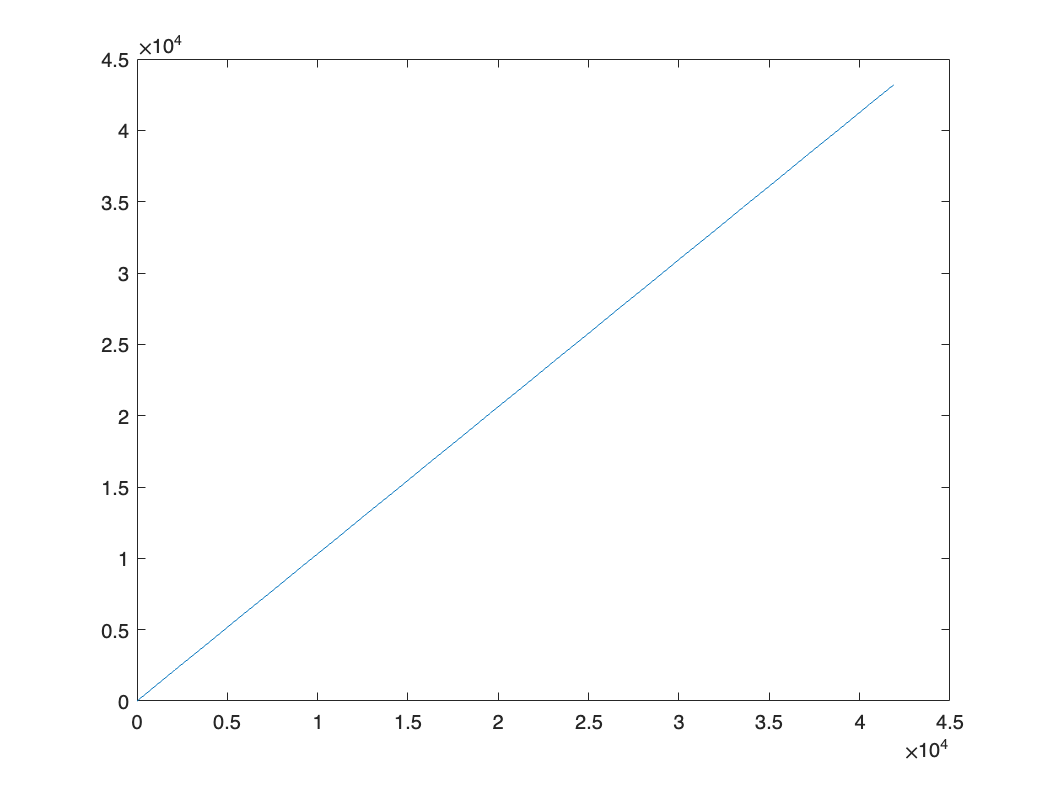

figure
plot(time_z_all_darkonly)

time_max = max(time_z_all_darkonly)

time_max = 4.3199e+04

length(time_z_all_darkonly)

ans = 41893

time_pooled = (2:4:(ceil(time_max/4)*4)) + 12*900;
% time_pooled = zeros(ceil(time_max/4),1);
tau_pooled = zeros(ceil(time_max/4),1);
states_pooled = zeros(ceil(time_max/4),1);

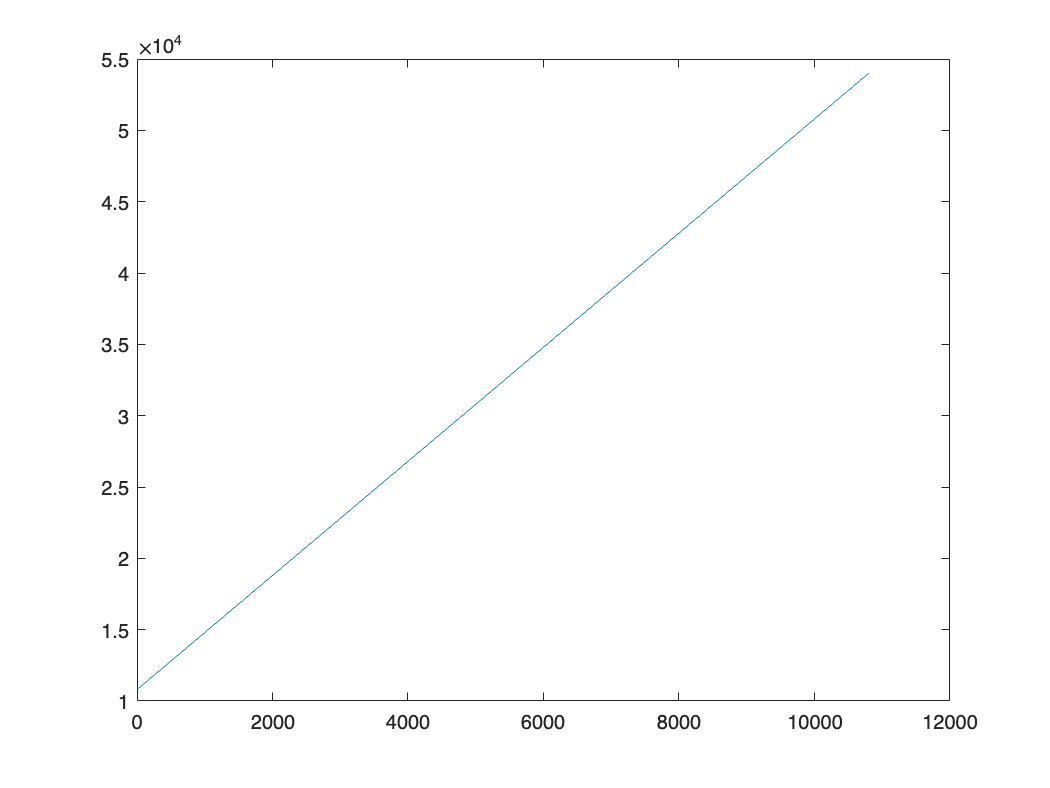

figure
plot(time_pooled)

circadian_time = (0:1:(length(time_pooled)-1)) + 10800;

ignored_index = find(circadian_time >= 10800 & circadian_time< 10800+2700);
tau_pooled(ignored_index) = [];


for i = 1:ceil(time_max/4)
    index = find(time_z_all_darkonly > (i-1)*4 & time_z_all_darkonly <= i*4);

    if isempty(index) == 0
        weighted_sum = sum(tau_empTrunc_all_darkonly(index).*intensity_all_darkonly (index));
        tau_pooled(i) = weighted_sum/sum(intensity_all_darkonly (index));
        states_pooled(i) = states_for_time_all_dark(index(1));
%         time_pooled(i) = time_z_all_darkonly(index(end));
    else
        tau_pooled(i) = tau_pooled(i-1);
        states_pooled(i) = states_pooled(i-1);
%         time_pooled(i) = NaN;

    end

    

end

sum(isnan(tau_pooled))

ans = 0

sum(isnan(states_pooled))

ans = 0

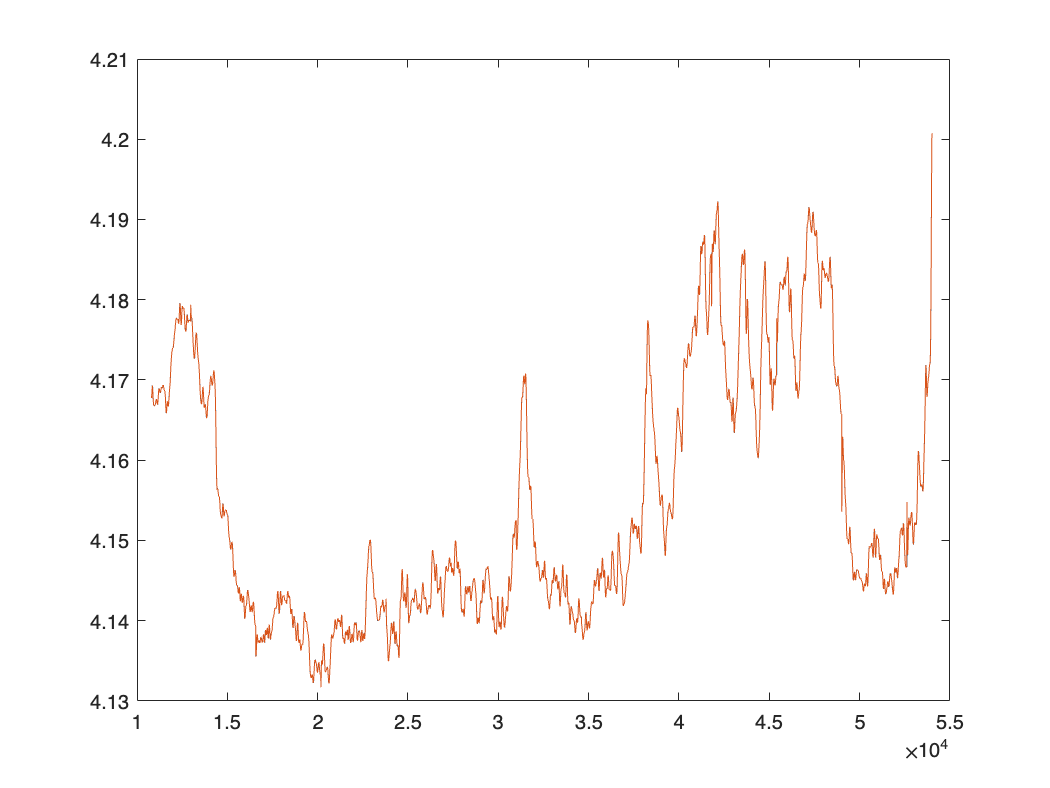

figure
plot(time_pooled, tau_pooled)
hold on
plot(time_z_all_darkonly+12*900, tau_empTrunc_all_darkonly)

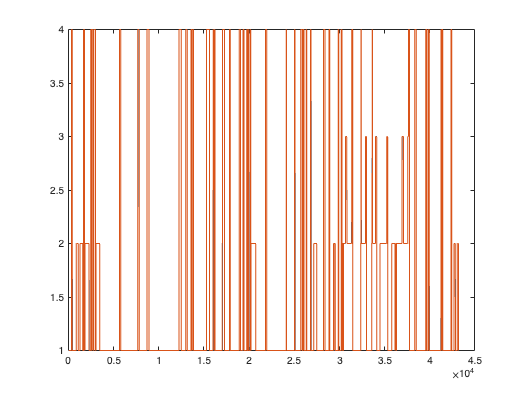

figure
plot(time_pooled, states_pooled)
hold on
plot(time_z_all_darkonly, states_for_time_all_dark)

states_pooled(find(states_pooled==2))=0;
states_pooled(find(states_pooled==3))=1;
states_pooled(find(states_pooled==4))=1;

length(states_pooled)

ans = 10800

ans = 10800

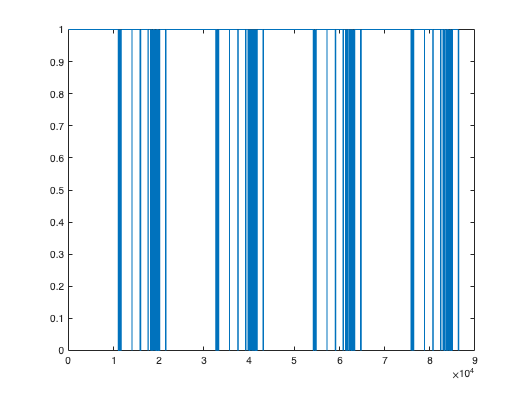

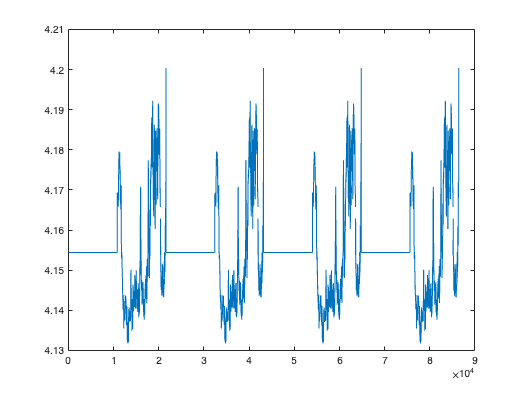

length(tau_pooled)

Temperature_path='/Users/pingchuanma/Desktop/ChenLab_Data/Lifetime_temperature/'

Temperature_path = '/Users/pingchuanma/Desktop/ChenLab_Data/Lifetime_temperature/'

cd(Temperature_path)

rawData = ([Temperature_path,ExperimentName,'_0920.mat'])

rawData = '/Users/pingchuanma/Desktop/ChenLab_Data/Lifetime_temperature/20220422_112_AChmtut_SW_001_0920.mat'

OptResults=([Temperature_path,ExperimentName,'OptResults_0920.mat'])

OptResults = '/Users/pingchuanma/Desktop/ChenLab_Data/Lifetime_temperature/20220422_112_AChmtut_SW_001OptResults_0920.mat'

save(rawData, 'circadian_time','states_pooled','tau_pooled')

example2_Optimization(rawData, 1, OptResults)

iteration 1/121: PWP values of size and shift are [0.25 , -5.0].
iteration 2/121: PWP values of size and shift are [0.25 , -4.0].
iteration 3/121: PWP values of size and shift are [0.25 , -3.0].
iteration 4/121: PWP values of size and shift are [0.25 , -2.0].
iteration 5/121: PWP values of size and shift are [0.25 , -1.0].
iteration 6/121: PWP values of size and shift are [0.25 , 0.0].
iteration 7/121: PWP values of size and shift are [0.25 , 1.0].
iteration 8/121: PWP values of size and shift are [0.25 , 2.0].
iteration 9/121: PWP values of size and shift are [0.25 , 3.0].
iteration 10/121: PWP values of size and shift are [0.25 , 4.0].
iteration 11/121: PWP values of size and shift are [0.25 , 5.0].
iteration 12/121: PWP values of size and shift are [1.25 , -5.0].
iteration 13/121: PWP values of size and shift are [1.25 , -4.0].
iteration 14/121: PWP values of size and shift are [1.25 , -3.0].
iteration 15/121: PWP values of size and shift are [1.25 , -2.0].
iteration 16/121: PWP val

load(OptResults)

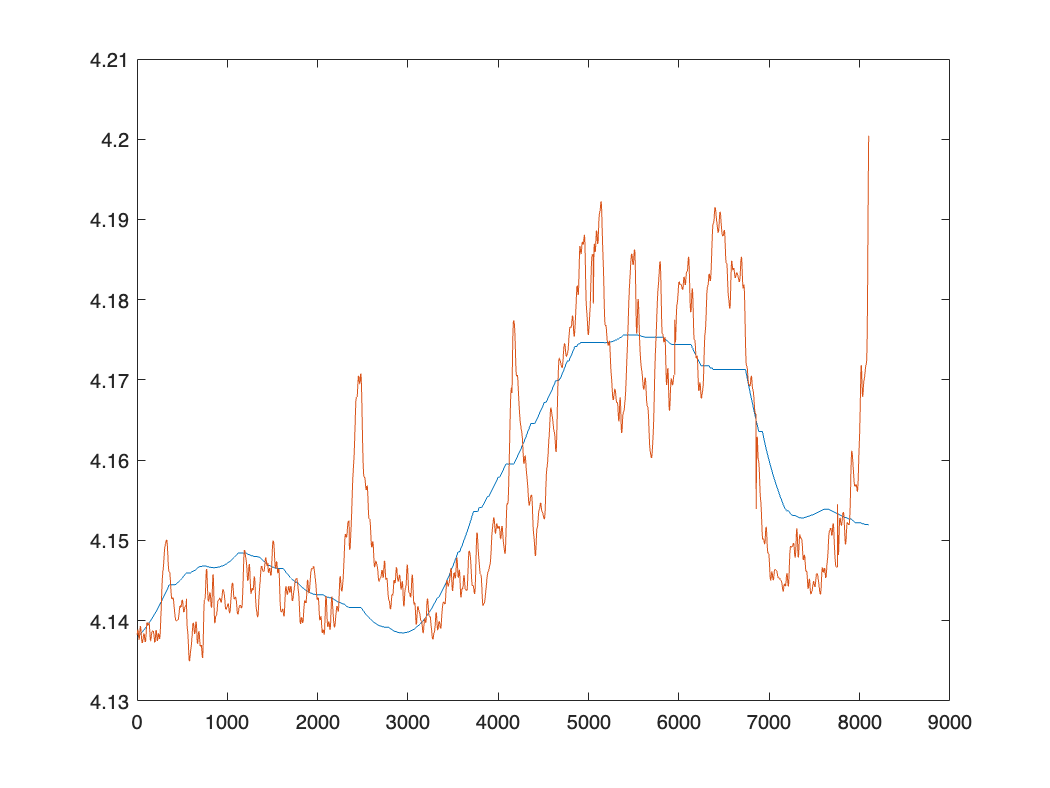

figure
plot(simulatedT)
hold on
plot(rawT)

c=parcluster

c = 

 Local Cluster

    Properties: 

                   Profile: local
                  Modified: false
                      Host: pingchuans-mbp
                NumWorkers: 21
                NumThreads: 1

        JobStorageLocation: /Users/pingchuanma/Library/Application Support/MathWorks/MATLAB/local_cluster_jobs/R2022a
   RequiresOnlineLicensing: false

    

j=batch(@example2_Optimization,1,{rawData, OptResults})

j = 

 Job

    Properties: 

                   ID: 50
                 Type: independent
             Username: pingchuanma
                State: running
       SubmitDateTime: 19-Sep-2022 16:16:06
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 